# Дополнительное задание к пятой лабе

ЛР 5. Синтезируйте систему управления из условия получения в ней стандартной настройки на «астатизм третьего порядка» с использованием эквивалентной непрерывной модели системы, учитывающей динамические свойства цифрового регулятора для случая Т1 >> Т0,  Т2 >> Т0 , ε = 0. Пришлите расчет регулятора скорости, а также формулы для вычисления коэффициентов цифрового регулятора скорости. Постройте график переходного процесса. Внимание! Не забывайте про учет дискретности системы управления и реализации ЦАП на выходе регулятора по методу Zoh.

Данные:

clear all
load('data.mat')

Найдем постоянные времени

ob.T1 = -(sqrt(-ob.J*(4*ob.Ce^2*ob.L - ob.J*ob.R^2)) - ob.J*ob.R)/(2*ob.Ce^2);
ob.T2 = (sqrt(-ob.J*(4*ob.Ce^2*ob.L - ob.J*ob.R^2)) + ob.J*ob.R)/(2*ob.Ce^2);
disp(ob.T1)

    0.0026



disp(ob.T2)

  245.9089



ob.kdw = 180/pi;
ob.Kob = ob.kdw/ob.Ce

ob = struct with fields:
      R: 10.6294
      L: 0.0281
      J: 92.5397
     Ce: 2
     Cm: 2
     T1: 0.0026
     T2: 245.9089
    kdw: 57.2958
    Kob: 28.6479


### ** a) Синтез регулятора скорости**

syms Tu T1 Kob T1 T2 s
Wob = Kob/(T1*s+1)/(T2*s+1);
Wol = (4*Tu*s+1)*(16*Tu*s+1)/(128*Tu^3*s^3*(Tu*s+1))

$$Wol = \frac{\left(4\,\mathrm{Tu}\,s+1\right)\,\left(16\,\mathrm{Tu}\,s+1\right)}{128\,{\mathrm{Tu}}^{3}\,s^{3}\,\left(\mathrm{Tu}\,s+1\right)}$$

Wreg = Wol/Wob;
disp(simplify(collect(Wreg,s)))

$$\frac{\left(T_{1}\,s+1\right)\,\left(T_{2}\,s+1\right)\,\left(64\,{\mathrm{Tu}}^{2}\,s^{2}+20\,\mathrm{Tu}\,s+1\right)}{128\,\mathrm{Kob}\,{\mathrm{Tu}}^{3}\,s^{3}\,\left(\mathrm{Tu}\,s+1\right)}$$

#### Расчет коэффициентов

syms Kpa2 Kda2 Kpa Kia Kiia Kiiia Kder
Kpa2 = 1;
Kda2 = T1;
collect(((T2*s + 1)*(64*Tu^2*s^2 + 20*Tu*s + 1))/(128*Kob*Tu^3*s^3),s)

$$ans = \frac{\left(64\,T_{2}\,{\mathrm{Tu}}^{2}\right)\,s^{3}+\left(64\,{\mathrm{Tu}}^{2}+20\,T_{2}\,\mathrm{Tu}\right)\,s^{2}+\left(T_{2}+20\,\mathrm{Tu}\right)\,s+1}{\left(128\,\mathrm{Kob}\,{\mathrm{Tu}}^{3}\right)\,s^{3}}$$

Kder = 128*Kob*Tu^3;
Kpa = 64*T2*Tu^2/Kder

$$Kpa = \frac{T_{2}}{2\,\mathrm{Kob}\,\mathrm{Tu}}$$

Kia = (64*Tu^2 + 20*T2*Tu)/Kder;
Kiia = (T2 + 20*Tu)/Kder;
Kiiia = 1/Kder;

#### Проверка

Wreg_t = ((Kda2*s+Kpa2)/(Tu*s + 1))*(Kpa+Kia/s+Kiia/s^2+Kiiia/s^3)

$$Wreg\_t = \frac{\left(T_{1}\,s+1\right)\,\left(\frac{T_{2}}{2\,\mathrm{Kob}\,\mathrm{Tu}}+\frac{1}{128\,\mathrm{Kob}\,{\mathrm{Tu}}^{3}\,s^{3}}+\frac{64\,{\mathrm{Tu}}^{2}+20\,T_{2}\,\mathrm{Tu}}{128\,\mathrm{Kob}\,{\mathrm{Tu}}^{3}\,s}+\frac{T_{2}+20\,\mathrm{Tu}}{128\,\mathrm{Kob}\,{\mathrm{Tu}}^{3}\,s^{2}}\right)}{\mathrm{Tu}\,s+1}$$

disp(simplify(collect(Wreg_t,s)))

$$\frac{\left(T_{1}\,s+1\right)\,\left(T_{2}\,s+1\right)\,\left(64\,{\mathrm{Tu}}^{2}\,s^{2}+20\,\mathrm{Tu}\,s+1\right)}{128\,\mathrm{Kob}\,{\mathrm{Tu}}^{3}\,s^{3}\,\left(\mathrm{Tu}\,s+1\right)}$$

### б) моделирование работы системы  настроенной на «астатизм третьего порядка»

Tmdl = 0.1;

To = 0.1 *ob.T1;
spl.Tur = 0.5*To;
spl.Tu = spl.Tur

spl = struct with fields:
    Tur: 1.3226e-04
     Tu: 1.3226e-04



% Kder = 128*Kob*Tu^3;
% Kpa = 64*T2*Tu^2/Kder
% Kia = (64*Tu^2 + 20*T2*Tu)/Kder;
% Kiia = (T2 + 20*Tu)/Kder;
% Kiiia = 1/Kder;

spl.Kder = 128*ob.Kob*spl.Tu^3

spl = struct with fields:
     Tur: 1.3226e-04
      Tu: 1.3226e-04
    Kder: 8.4830e-09


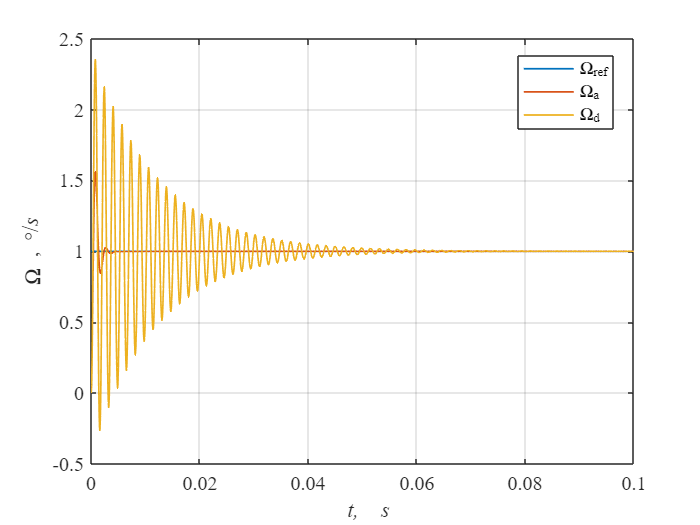

spl.Kpa = 64*ob.T2*spl.Tu^2/spl.Kder;
spl.Kia = (64*spl.Tu^2 + 20*ob.T2*spl.Tu)/spl.Kder;
spl.Kiia = (ob.T2+20*spl.Tu)/spl.Kder;
spl.Kiiia = 1/spl.Kder;

spl.Kpa2 = 1;
spl.Kda2 = ob.T1;


spl.Kpd = spl.Kpa;
spl.Kid = spl.Kia;
spl.Kiid = spl.Kiia;
spl.Kiiid = spl.Kiiia;

spl.Kd2dg = 1/(exp(To/ob.T1)-1);
spl.Kp2dg = 1;


warning off
b = sim('lab5_6_1','ReturnWorkspaceOutputs', 'on') ;
warning on

t = b.w(:,1);
wref = b.w(:,2);
wa = b.w(:,3);
wd = b.w(:,4);

h = figure;
set(h,'DefaultAxesFontSize',12,'DefaultAxesFontName', 'Times New Roman');

plot(t,wref,'LineWidth', 1)
hold on
grid on
plot(t,wa,'Linewidth', 1)
plot(t,wd,'Linewidth', 1)
xlabel('\it t,\rm \it s')
ylabel('\Omega \rm, \circ/\its')
legend('\Omega_{ref}', '\Omega_a', '\Omega_d','Location','best')

t переходного прцоесса tp1 5% зона -первое пересечение

t0=t(1);
y=wd;
y0=wd(1);
yss= wd(end);

D5=0.05*abs(yss-y0);
ind = abs(y-yss) < D5;
tn=t(ind);
ttr5= tn(1)-t0;
fprintf('Время перехода для 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время перехода для 5% зоны: 2.4*Tu

t переходного прцоесса tp2 5% зона - последнее значение за пределами 5% зоны

D5=0.05*abs(yss-y0);
ind = abs(y-yss) >= D5;
tn=t(ind);
ttr5= tn(end)-t0;
fprintf('Время перехода для 5%% зоны: %.1f*Tu', ttr5/spl.Tu)

Время перехода для 5% зоны: 303.2*Tu

dy = abs(max(y)-yss)/abs(yss-y0)

dy = 1.3554

Перерегулирование: 135.5%


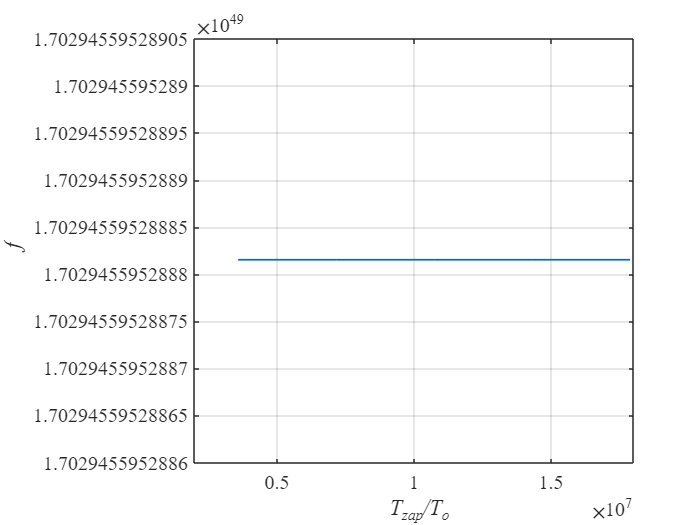

spl = struct with fields:
      Tur: 2.6451e-04
       Tu: 4.7612e-04
     Kder: 8.4830e-09
      Kpa: 3.2452e+04
      Kia: 7.6678e+07
     Kiia: 2.8989e+10
    Kiiia: 1.1788e+08
     Kpa2: 1
     Kda2: 0.0026
      Kpd: 3.2452e+04
      Kid: 7.6678e+07
     Kiid: 2.8989e+10
    Kiiid: 1.1788e+08
    Kd2dg: 9.5083
    Kp2dg: 1
       Tz: 2.1161e-04


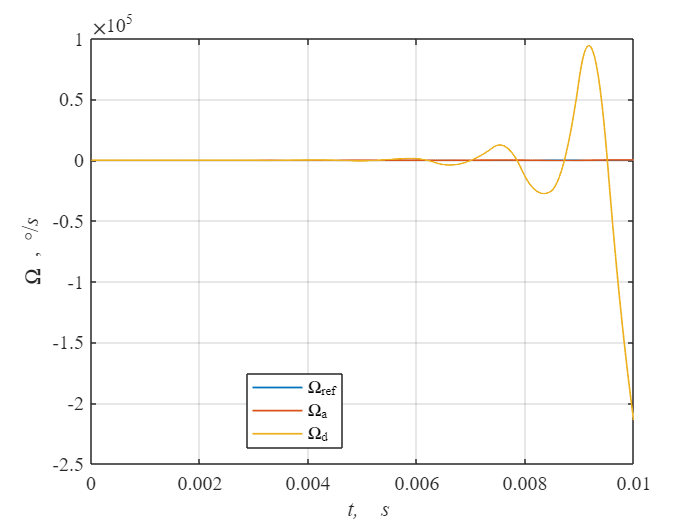

Время перехода для 5% зоны: 20.9*Tu

Время перехода для 5% зоны: 20.9*Tu

dy = 1.4404

Перерегулирование: 144.0%


fprintf('Перерегулирование: %.1f%%\n',dy*100)